Load values and labels

clear
load('./log_reg/datav5.mat')

Shuffle data

idx = randperm(size(dataMatrix,1));
shuffledData = dataMatrix(idx,:);
shuffledLabels = labels(idx,:);

Take 70% of the data for training and 30% for cross-validation

sizeTrainingSet = length(shuffledData) * 0.7

sizeTrainingSet = 786975

trainingSet = shuffledData(1:sizeTrainingSet,:);
trainingLabels = shuffledLabels(1:sizeTrainingSet,:);
xvalidationSet = shuffledData(sizeTrainingSet+1:end,:);
xvalidationLabels = shuffledLabels(sizeTrainingSet+1:end,:);

Train the logistic regression model

coeffs = glmfit(trainingSet,trainingLabels,'binomial','link','logit');
model = fitglm(trainingSet,trainingLabels,'Distribution','binomial','link','logit');

ROC with trained values

scores = model.Fitted.Probability;
[X,Y,T,AUC,OPTROCPT] = perfcurve(num2str(trainingLabels),scores,'1');
AUC

AUC = 0.5697

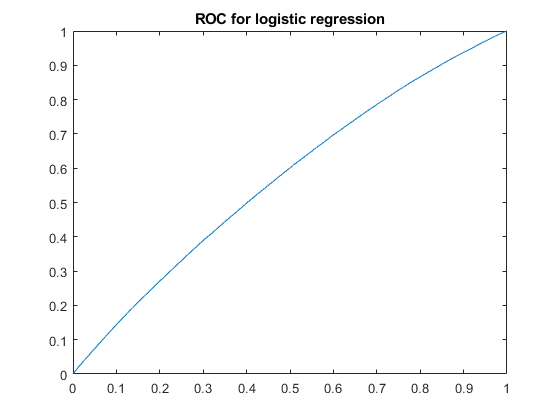

plot(X,Y)
title('ROC for logistic regression')

Version two: Differences

shuffledDatav2 = shuffledData(:,1:size(shuffledData,2)/2) - shuffledData(:,size(shuffledData,2)/2+1:end);
sizeTrainingSetv2 = length(shuffledDatav2) * 0.7

sizeTrainingSetv2 = 786975

trainingSetv2 = shuffledDatav2(1:sizeTrainingSetv2,:);
trainingLabels = shuffledLabels(1:sizeTrainingSetv2,:);
xvalidationSetv2 = shuffledDatav2(sizeTrainingSetv2+1:end,:);
xvalidationLabels = shuffledLabels(sizeTrainingSetv2+1:end,:);

Train the logistic regression model

coeffsv2 = glmfit(trainingSetv2,trainingLabels,'binomial','link','logit');
modelv2 = fitglm(trainingSetv2,trainingLabels,'Distribution','binomial','link','logit');

ROC with trained values

scoresv2 = modelv2.Fitted.Probability;
[X2,Y2,T2,AUC2,OPTROCPT2] = perfcurve(num2str(trainingLabels),scoresv2,'1');
AUC2

AUC2 = 0.5200

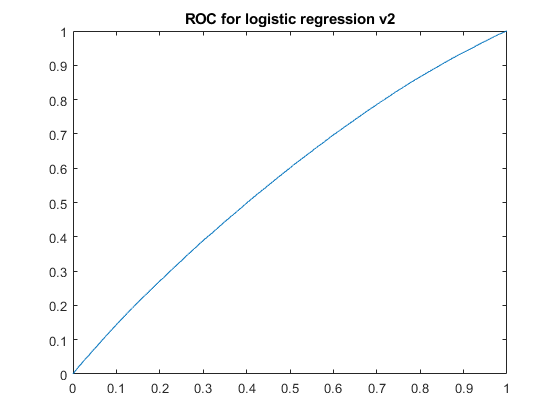

plot(X,Y)
title('ROC for logistic regression v2')